read

filename = "schos_va"

filename = "schos_va"

filepath_s = "./data/" + filename + "_HPR_S.wav";
[s, fs] = audioread(filepath_s);
s_ = s;
filepath_n = "./data/" + filename + "_HPR_N.wav";
[n, fs] = audioread(filepath_n);
n_ = n;
filepath_t = "./data/" + filename + "_HPR_T.wav";
[t, fs] = audioread(filepath_t);
t_ = t;
filepath_org = "./data/" + filename + ".wav";
[org, fs] = audioread(filepath_org);
org = org(1:length(s));

%sound(s(1:fs*2), fs); pause(2.5)
duration = length(s) / fs;

[b,a] = biquad_highshelf(fs/4+1000,6,0.6,fs);
s = highpass(filter(b,a,s), 30, fs);
n = highpass(filter(b,a,n), 30, fs);
t = highpass(filter(b,a,t), 30, fs);

まずWSOLA

tWR = wsolaTSM(resample(t, 2, 1), 0.5);
sWR = lowpass(wsolaTSM(resample(s, 2, 1), 0.5), fs/4, fs);
snWR = lowpass(wsolaTSM(resample(s+n, 2,1), 0.5), fs/4, fs);
nWR = wsolaTSM(resample(n,2,1),0.5);
orgWR = wsolaTSM(resample(org, 2, 1), 0.5);

% transient のみOLAが機能する可能性を持つ
paramOLA.tolerance = 0;
paramOLA.synHop = 256;
paramOLA.win = win(512,2); % hann window
tOLA = wsolaTSM(resample(t, 2, 1), 0.5, paramOLA);

それぞれ聞いてみる

sound(snWR+tOLA, fs); pause(duration)

わるくないかも→重音でワブる

nbi = shiftPitch(n, -12);
nbi_pl = shiftPitch(n, -12, "Window", sqrt(hann(1024, "periodic")), "LockPhase", true);
sbi = lowpass(highpass(shiftPitch(s, -12), 30,fs), fs/4, fs);
snbi = shiftPitch(s+n, -12);
tbi = shiftPitch(t, -12, "LockPhase",true);
soundsc(snbi+tbi  , fs); pause(duration)

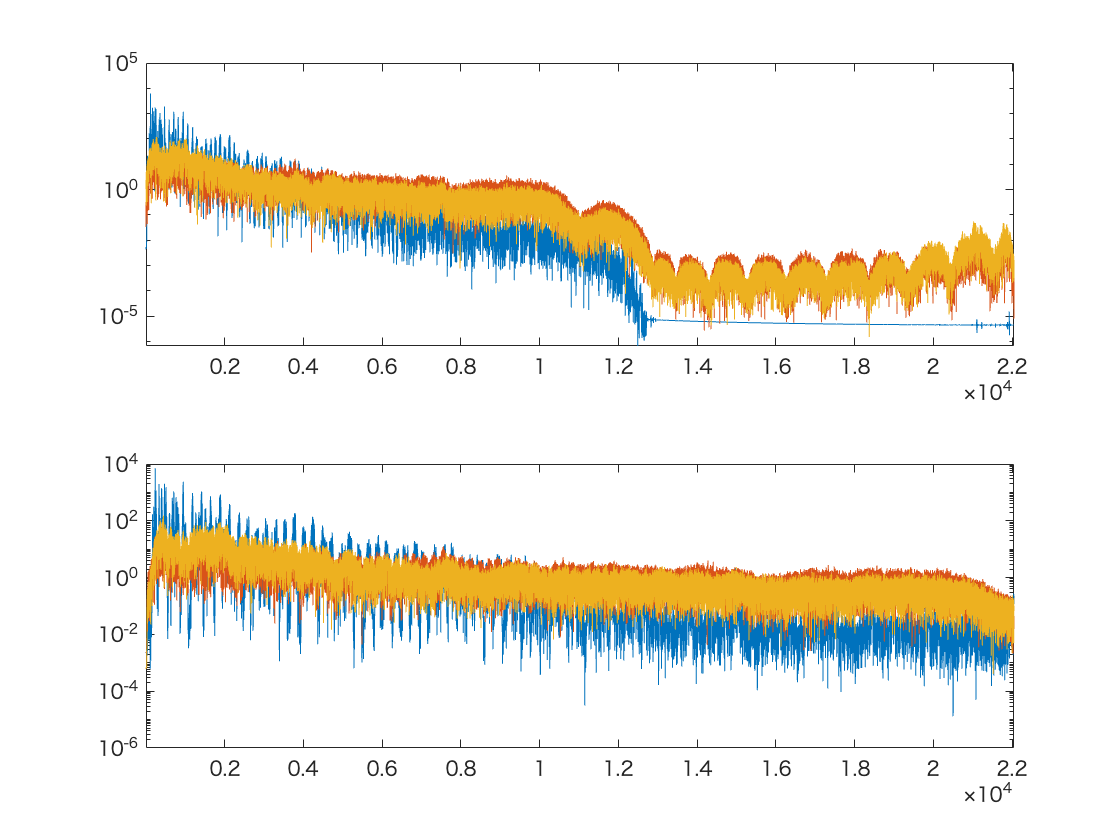

%% 重音でなければWSOLAが使える．（STNがうまくいっていれば重音でもいいはずだけど）
soundsc(sbi+nWR+tOLA,fs); pause(duration)
figure;
tiledlayout(2,1)
nexttile
axisFreq = (0:length(s)-1)/length(s)*fs;
semilogy(axisFreq, abs(fft(sbi))); 
hold on; 
semilogy(axisFreq, abs(fft(nWR))); 
semilogy(axisFreq, abs(fft(tOLA)))
xlim([1,fs/2])

nexttile
semilogy(axisFreq, abs(fft(s))); 
hold on; 
semilogy(axisFreq, abs(fft(n))); 
semilogy(axisFreq, abs(fft(t)))
xlim([1,fs/2])

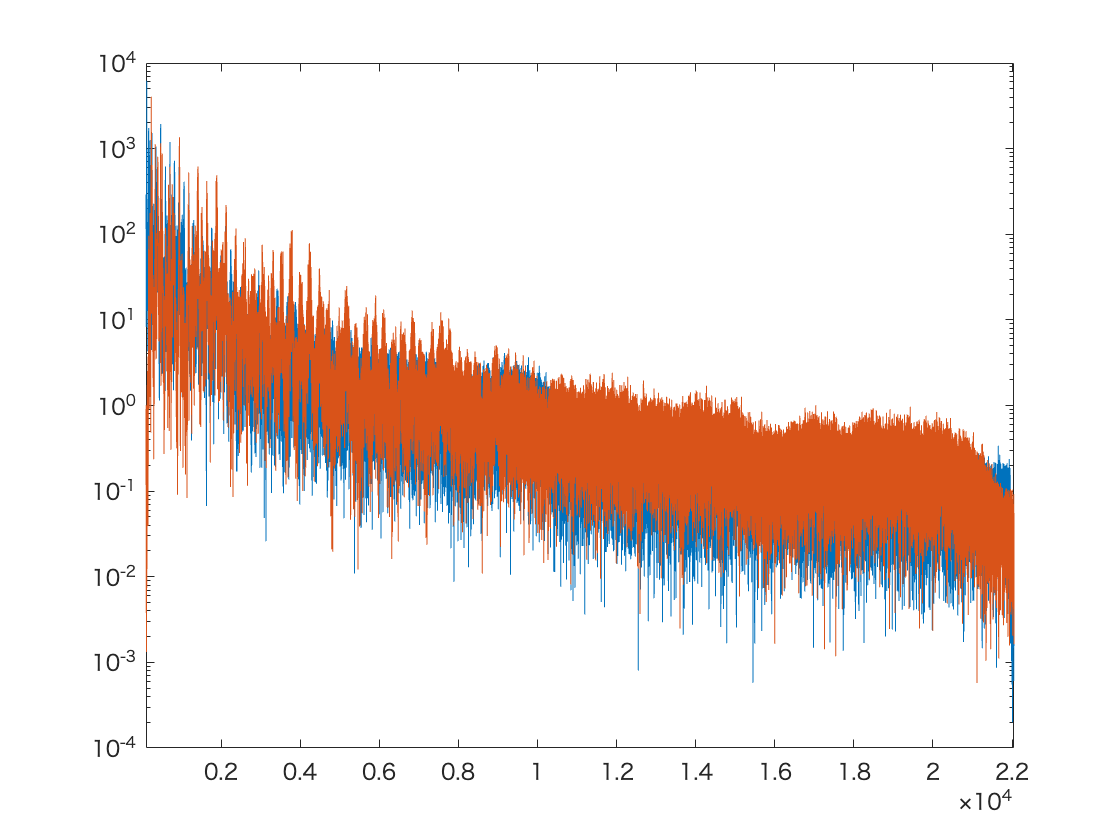

%sWR_harm = highpass(SoftClipper(lowpass(sWR, fs/4, fs, "steepness", 0.6)*1), 10000, fs, "steepness", 0.6);
sbi_found = lowpass(sbi, 400, fs, "steepness", 0.9);
amp_even = 0.5;
amp_odd_pre = 2;
amp_odd_post = 1;
sbi_odd = highpass(SoftClipper(sbi_found*amp_odd_pre)*amp_odd_post, fs/4, fs, "steepness", 0.9);
sbi_even = highpass(abs(sbi_found)*amp_even, fs/4, fs, "steepness", 0.9);
sbi_harm = lowpass(sbi_odd + sbi_even, fs/2-100,fs, "Steepness", 0.8);

nmix = lowpass(nWR, fs/4, fs) + 0.2*highpass(n_,fs/4,fs,"Steepness",0.9);
tmix = lowpass(tOLA, fs/4, fs) + 0.2*highpass(t_,fs/4,fs,"Steepness",0.9);
org_high = highpass(org, fs/4, fs);
res = sbi  + nmix + tmix + sbi_harm;
soundsc(res, fs)
%    highpass(tOLA + 0.3*abs(tOLA),30,fs), fs);
figure
semilogy(axisFreq, abs(fft(res)));
hold on
semilogy(axisFreq,abs(fft(org)))

xlim([100,fs/2])

**良さげ！（発表当日**）

figure; 
semilogy(abs(fft(orgHP(fs:2*fs))), "DisplayName", "HP-TSM");

関数または変数 'orgHP' が認識されません。

hold on
semilogy(abs(fft(orgWR(fs:2*fs))), "DisplayName", "WSOLA");
semilogy(abs(fft(orgWR(fs:2*fs))), "DisplayName", "WSOLA");
xlim([50, 1000])